# Integration of Filippov behaviour in switched ODE systems

When integrating a switched system, rapid switching behavoiur can occur if the vector fields (created by the RHS) point towards each other around the switch. This is called **Filippov switching behaviour**. A naive integrator such as the explicit euler (but also more sophisticated ones such as ode45) fails to capture the fact that in such a case the solution slides along the so called switching manifold (a body in the solution space containing all points, where the RHS branches to different versions).

Even an *accurate* Euler as shown further down in the document cannot capture a sufficiently accurate trajectory and takes up a lot of computational time, effort and working memory. `IFDIFF` on the other hand can spot such behaviour stepping **along** the corresponding surface using information of both neighboring models in a convex combination. In this case the linked integrator can still choose adaptive step sizes and shows no real drop in performance.

## A switched Predator-Prey model

First the differential equation is initialized. Its formualtion can be found [here](matlab:open('..\predatorpreyFilippov\predatorPrey3D_rhs.m')).

%% Setup
% Time span
tspan = [0, 100];

% Integrator
intIfdiff  = @ode45;
intOptions = odeset('reltol', 1e-5, 'abstol', 1e-12);
eulerStep = 1e-7;

% Parameter values required for Shilnikov behavior in the paper (see RHS file).
m     = 0.790;
r1    = 0.836;
e     = 0.948;
q1    = 0.772;
aq    = 0.660;
beta2 = 0.896;
% Some values changed for prettier plot (remains a Filippov system).
q2    = 1.500; % 1.084 (paper)
r2    = 0.300; % 0.126 (paper)
beta1 = 7.810; % 7.800 (Example plot in paper, but can be chosen arbitrarily, retaining Shilnikov behavior)
p = [r1, r2, beta1, beta2, q1, q2, m, e, aq];

% Initial values (used for plot in paper, but may be changed)
a  = 0.286975;
x0 = [a; a; r1-r2];

% RHS function dx = f(t, x, p), must be implemented in separate file for IFDIFF.
rhs = @rhsPredatorPrey3D;

% Plotting
plot_n = 10000;
plot_t = linspace(tspan(1), tspan(end), plot_n);

nameIfdiff = sprintf('Ifdiff/%s', func2str(intIfdiff));
nameEuler = sprintf('Euler/%.0e', eulerStep);
lwIfdiff = 3;
lwEuler = 3;
colorIfdiff = [0, 0.447, 0.741];
colorEuler = [0.85, 0.325, 0.098];
lsIfdiff = '-';
lsEuler = '--';

% Sensitivity
wrt_y = 3;
eulerDisturbH = 1e-6;


As was already mentioned, the "accurate" Euler solution is only loaded from a precomputed file as the computation with the above stepsize takes quite long. Even so the Euler-solution is not at all accurate, since the corresponding algorithm doesn't account for any of the switches (which in this case are thousands). As much can be seen in the difference plot below.

datahandle = prepareDatahandleForIntegration(rhs, 'solver', intIfdiff, 'options', intOptions);
% Enable storing of convexification data
configNew = makeConfig();
configNew.storeSlidingInfo = true;
configOld = makeConfig(configNew);
try
    solIfdiff = solveODE(datahandle, tspan, x0, p);
catch ME
    makeConfig(configOld);
    rethrow(ME);
end

makeConfig(configOld);

%% Solve with Euler
[owndir, ~] = fileparts(mfilename('fullpath'));
if contains(owndir, 'Editor_')
    [owndir, ~] = fileparts(matlab.desktop.editor.getActiveFilename);
end

euler_prefix = sprintf('sol_euler_%.0e', eulerStep);
euler_vname = 'sol_euler';
euler_fname = fullfile(owndir, [euler_prefix, '.mat']);

solEuler = loadEulerOrComputeLive(euler_fname, euler_vname, rhs, tspan, x0, p, eulerStep);

Integrating with explicit Euler (might take a while) ...
....................................................................................................
Saving result to /home/pilar/ifdiff/toolbox/examples/liveExamples/sol_euler_1e-07.mat for later reuse.


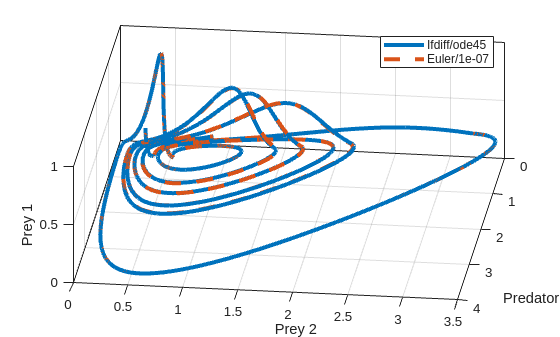

%% Plot solution
plot_x_ifdiff = deval(solIfdiff, plot_t);
axSol = plotSol3DLive([], plot_x_ifdiff, nameIfdiff, lwIfdiff, colorIfdiff, lsIfdiff);

plot_x_euler = interp1(solEuler.x, solEuler.y', plot_t)';
plotSol3DLive(axSol, plot_x_euler, nameEuler, lwEuler, colorEuler, lsEuler);

## Creating a Difference Plot to check Accuracy

However, we ar now interested in seing how far these trajectories deviate. We do that by taking the euklidian norm of the difference since the states are vectors themselves. Then we plot it against the time horizon.

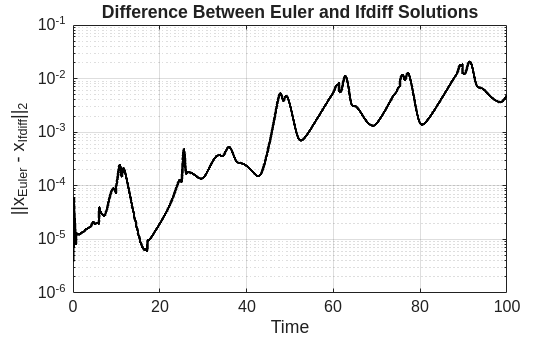

diff_x = plot_x_euler - plot_x_ifdiff;
diff_norm = vecnorm(diff_x, 2, 1);

figure;
semilogy(plot_t, diff_norm, 'k', 'LineWidth', 2);
xlabel('Time');
ylabel('||x_{Euler} - x_{Ifdiff}||_2');
title('Difference Between Euler and Ifdiff Solutions');
grid on;
set(gca, 'FontSize', 12);